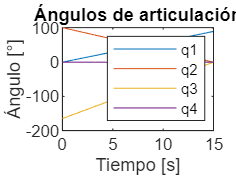

close all;

n = 15;

q1Val = linspace(0,90,n);%zeros(1,n);
q2Val = linspace(101.10, 0, n);
q3Val = linspace(-165,0,n);
q4Val = zeros(1,n);

figure()
time = linspace(0,15,length(q1Val));
plot(time,q1Val);
hold on
plot(time,q2Val);
plot(time,q3Val);
plot(time,q4Val);
legend('q1','q2','q3','q4')
title('Ángulos de articulación');
xlabel('Tiempo [s]')
ylabel('Ángulo [°]')


deltaT = time(2)-time(1);

q1Val = q1Val*(pi()/180);
q2Val = q2Val*(pi()/180);
q3Val = q3Val*(pi()/180);

q1pVal = [0 diff(q1Val)/deltaT];
q1p2Val = [0 diff(q1pVal)/deltaT];

q2pVal = [0 diff(q2Val)/deltaT];
q2p2Val =[0 diff(q2pVal)/deltaT];

q3pVal = [0 diff(q3Val)/deltaT];
q3p2Val =[0 diff(q3pVal)/deltaT];